clc
data=load('data1.txt')

data =     1.0000    1.5000    3.0000    5.0000   10.0000   20.0000   45.0000   50.0000   30.0000    2.0000    1.0000    0.5000
    3.5000    3.0000    5.0000    9.0000   11.0000   24.0000   49.0000   50.0000   31.0000    4.0000    4.0000    3.5000
    7.0000    6.0000    8.0000    9.0000   15.0000   25.0000   52.0000   55.0000   37.0000    7.0000    5.0000    6.0000


% Create a plot of the data
xt=(data);
yt=xt(:);
[n,m]=size(data)

n = 3

m = 12

% k pair
% Define the parameters
k = 12;  % value of k
l = k/2;  % value of m
T=length(yt);
% Calculate the rolling mean using the formula
rolling_means=zeros(T,1);
for i=k:T-k
    rolling_means(i-1) = 0.5*(yt(i-k+1))+ sum(yt(i-k+2:i)) + 0.5*(yt(i+k)) / k;   
end
disp(rolling_means)

         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
   62.7917
   69.5000
   75.2917
   86.2917
  102.5833
  122.1667
  142.7917
  183.5417
  226.1667
  271.7083
  314.5208
  355.6458
  401.2500
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0
         0



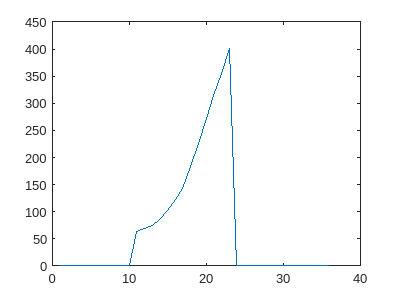

plot(rolling_means)